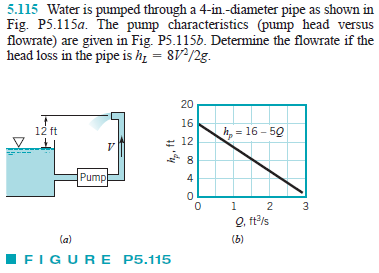

# constants

u = symunit;
gamma = 64.2*u.lbf/u.ft^3;
rho = 1.94*u.slug/u.f^3;
g = 32.2*u.ft/u.s^2;

# inflow properties

p1 = 0;
V1 = 0;
z1 = 0;

# outflow properties

syms Q positive;
p2 = 0;
D2 = 4*u.in;
A2 = sympi*D2^2/4;
V2(Q) = rewrite(Q/A2, 'US');
z2 = 12*u.ft;

# conservation of energy

hs(Q) = 16*u.ft-5*u.s/u.ft^2*Q;
hL = 8*V2^2/(2*g);
Q = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1+hs-hL);
Q_vpa = vpa(Q, 2) %#ok

$$Q\_vpa = 0.35\,\frac{{\mathrm{ft}}^{3}}{s}$$

clear Q_vpa;
clearassum;